### Add proper path to helper folder

currentLocation = pwd;
addpath(fullfile(currentLocation, "/helpers"))

## Preprocessing Data

% Initialize variables to load datasets
finaldataset = dir('./data/dataset*.mat');
n = size(finaldataset,1);

% Initialize variables taken from anotherDay.mat example
Fs = 1000;
actualFs = 997.8331;
label_names = [1;2;3]; % 1 for rock, 2 for scissors, 3 for paper
numCh = 4; % 4 sEMG channels

% Process data for variables that are ready to be trained
[dataChTimeTr, labels] = preprocessing(finaldataset, n);

**Save processed data (dataChTimeTr) into a mat file**

save('./helpers/matFiles/processedData.mat', 'dataChTimeTr', 'labels', 'Fs', 'actualFs', 'label_names', 'numCh');

## Generate a Feature Table

% Make a list of features to include using findings from histograms from
% analysis of precollected data
includedFeatures = {'var','std', 'rms', 'mav'};
feature_table = extractFeatures(dataChTimeTr, includedFeatures, Fs);

**Save feature table into a mat file**

save('./helpers/matFiles/feature_table.mat','feature_table','labels');

## **Perform cross-validation on the selected features**

This is to test which classifier method to use

**Select a subset of features**

filesToLoad = {"./helpers/matFiles/feature_table.mat"};
load(filesToLoad{1})
% Uncomment the line below to select all features
selected_features = 1:size(feature_table,2);
% Uncomment the line below to select 2 features
% selected_features = [1 2]; 

clearvars feature_table label % Clear the labels used to extract features

**Load feature data into X-Y matrices**

Look inside featuresTo_X_y_train_test.m to set things like train-test split.

% Load the feature data and put into X and y matrices
[X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features);

Making new training-test partiton



% Perform cross-validation
KFolds = 5;
cvp_kfold = cvpartition(y_train, 'KFold', KFolds);

% Make empty vector to store predictions from k-fold cross-validation
validation_predictions = NaN(length(y_train),1);

% Loop through all the folds
for fold = 1:KFolds
    % Within each partition, assign the data for that fold to the
    % cross-validation training data
    kfold_partial_data_X_train = X_train(cvp_kfold.training(fold), :);
    kfold_partial_data_y_train = y_train(cvp_kfold.training(fold), :);
    
    % Within each partition, assign the data for that fold to the
    % cross-validation validation (testing) data
    kfold_partial_data_X_val = X_train(cvp_kfold.test(fold), :);
    %kfold_partial_data_y_val = y_train(cvp_kfold.test(fold), :);

    % Build a temporary model for this subset of the data (k-1)/k
    kfold_classifier = createClassifier(kfold_partial_data_X_train,kfold_partial_data_y_train);

    % Make predictions with the kfold_classifier  (temporary classifier on
    % subset of data)
    kfold_predictions = kfold_classifier.predict(kfold_partial_data_X_val);

    % Store predictions in the original order
    validation_predictions(cvp_kfold.test(fold), :) = kfold_predictions;
end

## Classification

% Create a classifier and save it to a .mat file
currentClassifier = createClassifier(X_train, y_train);
save('./helpers/matFiles/classifier.mat', 'currentClassifier');

% Use classifier to predict on training data (resubstitution)
y_train_predictions = currentClassifier.predict(X_train);
[train_accuracy, train_confusion] = calculateMetrics(y_train, y_train_predictions);
disp('Training Metrics:');

Training Metrics:


disp(['Accuracy: ' num2str(train_accuracy)]);

Accuracy: 0.82344


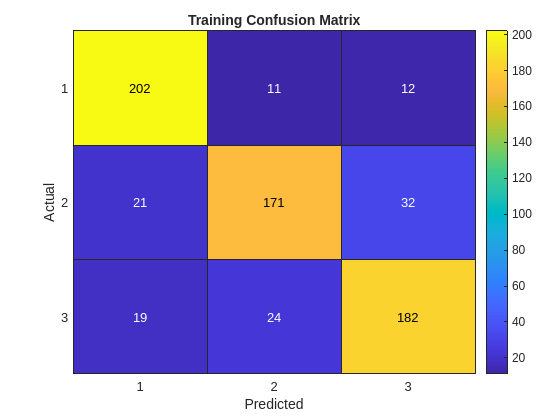


% Create a heatmap for the training confusion matrix
figure;
h = heatmap(train_confusion, 'Colormap', parula);
h.Title = 'Training Confusion Matrix';
h.XLabel = 'Predicted';
h.YLabel = 'Actual';


% Calculate cross-validation metrics
[validation_accuracy, validation_confusion] = calculateMetrics(y_train, validation_predictions);
disp('Validation Metrics:');

Validation Metrics:


disp(['Accuracy: ' num2str(validation_accuracy)]);

Accuracy: 0.68398


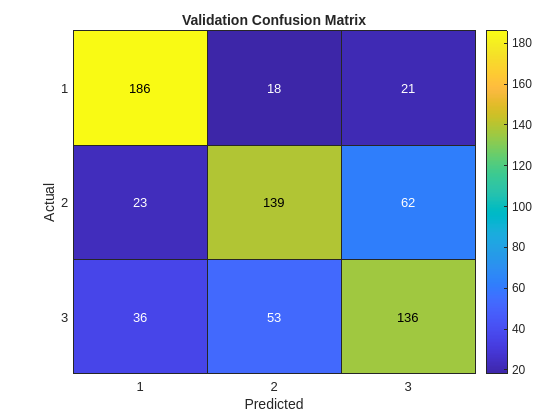


% Create a heatmap for the cross-validation confusion matrix
figure;
h = heatmap(validation_confusion, 'Colormap', parula);
h.Title = 'Validation Confusion Matrix';
h.XLabel = 'Predicted';
h.YLabel = 'Actual';

## Running Classifier on Test Data

% Use classifier to predict on testing data
y_test_predictions = currentClassifier.predict(X_test);

% Calculate testing metrics
[test_accuracy, test_confusion] = calculateMetrics(y_test, y_test_predictions);
disp('Testings Metrics:');

Testings Metrics:


disp(['Accuracy: ' num2str(validation_accuracy)]);

Accuracy: 0.68398


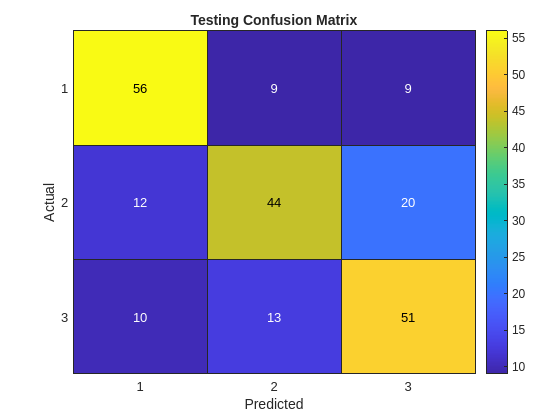


% Create a heatmap for the testing confusion matrix
figure;
h = heatmap(test_confusion, 'Colormap', parula);
h.Title = 'Testing Confusion Matrix';
h.XLabel = 'Predicted';
h.YLabel = 'Actual';